## Exercise 3

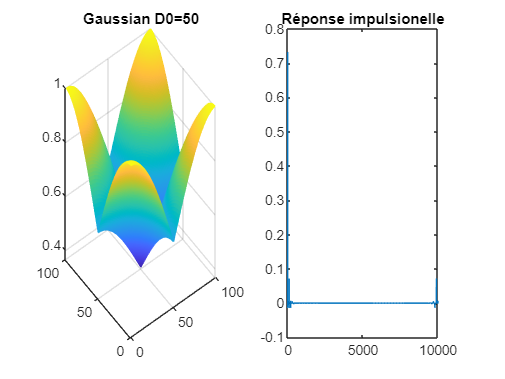

%Lowpass filter
I=lpfilter('gaussian',100,100,50);
figure,
subplot(1,2,1),mesh(I),title('Gaussian D0=50')
i = ifft2(I);
subplot(1,2,2),plot(real(i(:))),title('Réponse impulsionelle');

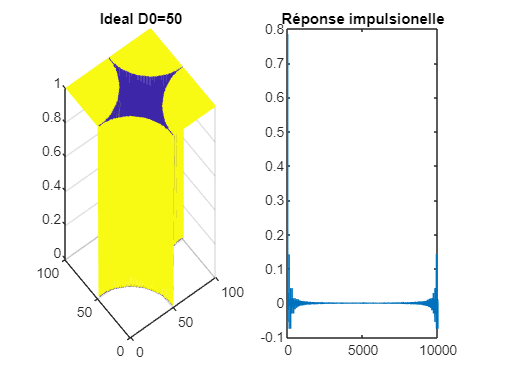


II=lpfilter('ideal',100,100,50);
figure,
subplot(1,2,1),mesh(II),title('Ideal D0=50')
ii = ifft2(II);
subplot(1,2,2),plot(real(ii(:))),title('Réponse impulsionelle');

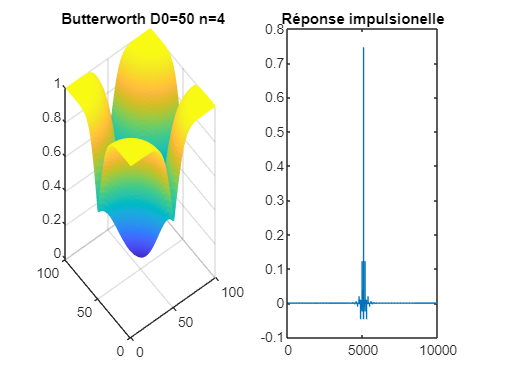


III=lpfilter('btw',100,100,50,4);
figure,
subplot(1,2,1),mesh(III),title(' Butterworth D0=50 n=4')
iii = fftshift(ifft2(III));
subplot(1,2,2),plot(real(iii(:))),title('Réponse impulsionelle');

### A.3.1

H_highpass=1-H_lowpass

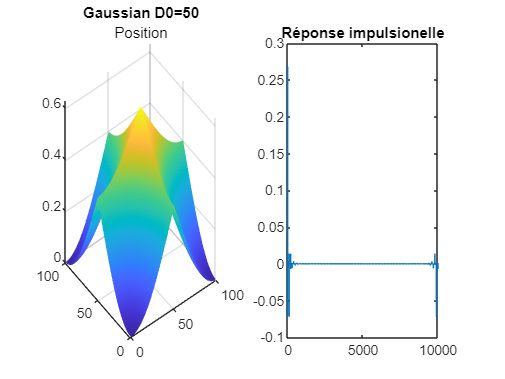

%Highpass filter
HI=1-lpfilter('gaussian',100,100,50);
figure,
subplot(1,2,1),mesh(HI),title('Gaussian D0=50')
hi = ifft2(HI);
subplot(1,2,2),plot(real(hi(:))),title('Réponse impulsionelle');

### A.3.2

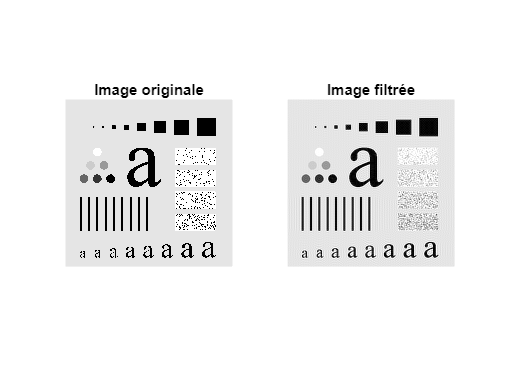

TEST = imread('Fig_test_pattern.tif');

% Get the size of the image
[M, N] = size(TEST);

% Define the filter parameters
D0 = 0.1*max(M, N); % Cutoff frequency

H = lpfilter('ideal', M, N, 100);
   
% Pad the filter and the image to the same size
H_padded = padarray(H, [M-N, 0], 'post');
I_padded = padarray(TEST, [M-N, 0], 'post');

I_filtered = ifft2(fft2(I_padded).*H_padded);


I_filtered_cropped = I_filtered(1:M, 1:N);

% Affichage
figure;
subplot(1,2,1);
imshow(TEST);
title('Image originale');
subplot(1,2,2);
imshow(uint8(abs(I_filtered_cropped)));
title('Image filtrée');

### A.3.3

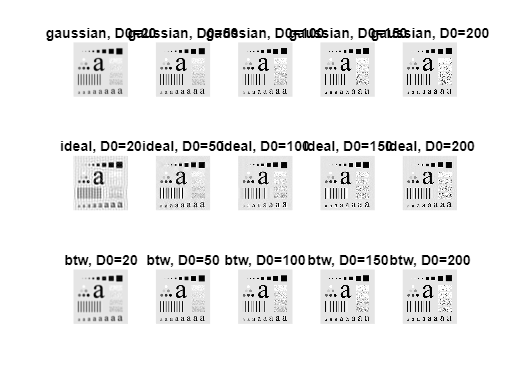

TEST = imread('Fig_test_pattern.tif');

[M, N] = size(TEST);

filter_types = {'gaussian', 'ideal', 'btw'};
D0_values = [20, 50, 100, 150, 200];

figure;
sgtitle('Filtres passe-bas')
subplot_idx = 1;
for i = 1:length(filter_types)
    for j = 1:length(D0_values)
        % Filtres
        switch filter_types{i}
            case 'gaussian'
                H = lpfilter('gaussian', M, N, D0_values(j));
            case 'ideal'
                H = lpfilter('ideal', M, N, D0_values(j));
            case 'btw'
                H = lpfilter('btw', M, N, D0_values(j), 2);
        end
        
        
        H_padded = padarray(H, [M-N, 0], 'post');
        I_padded = padarray(TEST, [M-N, 0], 'post');

        I_filtered = ifft2(fft2(I_padded).*H_padded);

        I_filtered_cropped = I_filtered(1:M, 1:N);

        %Affichage
        subplot(length(filter_types), length(D0_values), subplot_idx);
        imshow(uint8(abs(I_filtered_cropped)));
        title(sprintf('%s, D0=%d', filter_types{i}, D0_values(j)));

        subplot_idx = subplot_idx + 1;
    end
end

Comme nous pouvons le voir sur les images, le filtrage passe-bas a pour effet de lisser l’image en réduisant le contenu à haute fréquence. La nature exacte du lissage dépend du type de filtre (gaussien, idéal ou Butterworth) et de la fréquence de coupure utilisée (D0). Les filtres gaussiens produisent un résultat plus lisse que les filtres Butterworth, et le filtre idéal produit le résultat le plus lisse de tous. L’augmentation de la fréquence de coupure a pour effet de conserver plus de contenu à haute fréquence, ce qui donne une image plus nette avec plus de détails, mais aussi plus de bruit.

De plus, on peut voir sur le résultat du filtre idéal des tâches rondes (très visible sur le D0=20). Cela est dû à un phénomène appelé anneau de Gibbs, qui se produit lorsque l'on essaie de reconstruire une fonction périodique à partir de ses composantes de Fourier discrètes. Lorsque l'on utilise un filtre idéal, qui coupe brutalement toutes les fréquences supérieures à la fréquence de coupure, cela entraîne une discontinuité brusque dans les coefficients de Fourier, ce qui peut causer des oscillations (ou des anneaux) dans la région de transition entre les fréquences coupées et les fréquences conservées. Ces anneaux peuvent être particulièrement visibles autour des bords des objets dans une image, car les bords sont souvent caractérisés par des hautes fréquences. Les filtres gaussiens et Butterworth sont moins sujets à cet effet car ils ont une transition plus douce entre les fréquences coupées et conservées.

## A.3.4

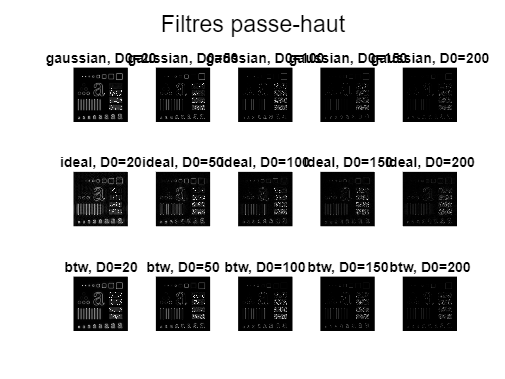

TEST = imread('Fig_test_pattern.tif');

[M, N] = size(TEST);

filter_types = {'gaussian', 'ideal', 'btw'};
D0_values = [20, 50, 100, 150, 200];

figure;
sgtitle('Filtres passe-haut')
subplot_idx = 1;
for i = 1:length(filter_types)
    for j = 1:length(D0_values)
        % Filtres
        switch filter_types{i}
            case 'gaussian'
                H = 1-lpfilter('gaussian', M, N, D0_values(j));
            case 'ideal'
                H = 1-lpfilter('ideal', M, N, D0_values(j));
            case 'btw'
                H = 1-lpfilter('btw', M, N, D0_values(j), 2);
        end
        
        
        H_padded = padarray(H, [M-N, 0], 'post');
        I_padded = padarray(TEST, [M-N, 0], 'post');

        I_filtered = ifft2(fft2(I_padded).*H_padded);

        I_filtered_cropped = I_filtered(1:M, 1:N);

        %Affichage
        subplot(length(filter_types), length(D0_values), subplot_idx);
        imshow(uint8(abs(I_filtered_cropped)));
        title(sprintf('%s, D0=%d', filter_types{i}, D0_values(j)));

        subplot_idx = subplot_idx + 1;
    end
end

L'effet du filtrage passe-haut est de supprimer les composantes de basses fréquences d'une image, mettant en évidence les détails à haute fréquence. Cela peut être utile pour améliorer la netteté des images ou pour mettre en évidence des caractéristiques plus visibles à des fréquences plus élevées.

La principale différence entre les trois types de filtres (gaussien, idéal et Butterworth) réside dans la manière dont ils atténuent les différentes fréquences de l'image. Les filtres gaussiens ont une réponse en fréquence lisse en forme de cloche qui réduit les amplitudes de toutes les fréquences, les fréquences plus élevées étant atténuées plus fortement que les fréquences plus basses. Les filtres idéaux, quant à eux, ont une fréquence de coupure nette au-delà de laquelle toutes les fréquences sont complètement atténuées, entraînant l'effet de réverbération dont nous avons discuté précédemment. Les filtres Butterworth ont une réponse en fréquence qui diminue progressivement au-delà de la fréquence de coupure, ce qui peut fournir une transition plus douce entre les fréquences atténuées et préservées.